# Lecture 2 Linear System

Thanks to the popularity of photo editing tools, the word "filter" is often used as a synonym for any type of image manipulation. Have you ever wondered why it is called filtering in the first place? When we talk about filtering, it usually means some things pass through while others are blocked. For example, a water filter has a physical barrier that blocks debris and bacteria from passing through, while allowing water molecules to flow through. Similarly, when we manipulate an image, there is an input image and an output image. Certain information of the input passes through while other information does not. To build a mathematical model describing this process for imaging, we will introduce some basic concepts.

## 1. System

A system maps a set of input signals to a set of output signals. For an imaging system, the inputs are the scenes being imaged, and the outputs are the resultant photos or signals from an imaging sensor. The input and output images are the functions of the spatial position $\left(x,y\right)$. For simplicity, we start with a one-dimensional time series (i.e., the signal is a function of time *t*). 

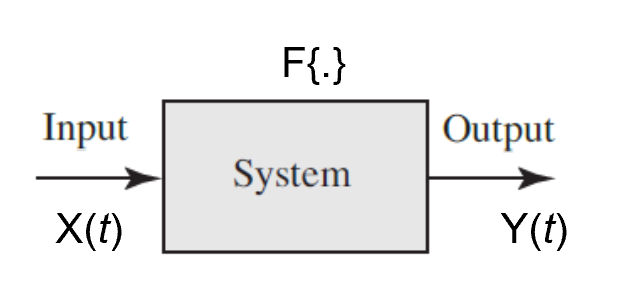

**ILL 1.1*** System block diagram with X(t) as the input and Y(t) as the output.*

### 1.1 Continuous and discrete signals

***Continuous signal***: a signal that continuously and infinitely varies over time. These signals are also called analog signal and are denoted with a continous function with variables in round bracket (*e.g.*, $x\left(t\right)$ ). As an example, the continous *Dirac delta function* is defined as:


$$\delta \left(t\right)=\left\lbrace \begin{array}{ll}
\infty  & t=0\\
0 & t\;\not= 0
\end{array}\right.$$


and $\int_{-\infty }^{\infty } \delta \left(t\right)\textrm{dt}=1$

***Discrete signal***: a signal that is represented by a sequence of values that correspond to particular instances in time. Mathmatically, the signal is denoted by a series with indices in square brackets, (*e.g.*, $x\left\lbrack n\right\rbrack ,\;n=0,1,2,\ldotp \ldotp \ldotp$) . The discrete signal corresponds to the Dirac delta function is called unit sample function $\delta \left\lbrack n\right\rbrack$ and is defined as 


$$\delta \left\lbrack n\right\rbrack \equiv \delta_{n,0\;} =\left\lbrace \begin{array}{ll}
1 & n=0\\
0 & n\;\not= 0
\end{array}\right.$$


where $\delta_{i,j\;}$ is the *Kronecker delta function* is defined as:


$$\delta_{i,j} =\left\lbrace \begin{array}{ll}
1 & i=j\\
0 & i\;\not= j
\end{array}\right.$$


***Example 1.1 ***

Simple signal and system examples in MATLAB.

Using numerical methods, all the signals are represented as finite arrays with finite precision (i.e., discrete signals). The plot may appear to be a contiuous curve using MATLAB `plot()`, but using `stem()` you will see the descrete signal. See the example below. 

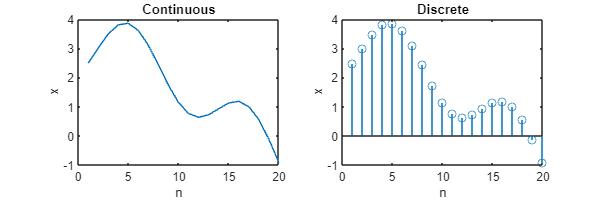

N =20; % number of points
M =2; % shift along the x-axis

x=sin(pi.*((1:N)-M)/6)+3*cos(pi.*((1:N)-M)/30); 

figure;
subplot(121);
plot(x); % Appear to be continous for the plot
title ('Continuous');xlabel ('n');ylabel ('x');

subplot(122);
stem(x); % Appear to be discrete
title ('Discrete');xlabel ('n');ylabel ('x');

set(gcf,'Position',[100 100 600 200]);

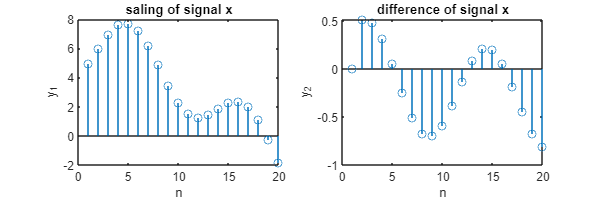

% scaling and difference operation on the input
alpha = 2; % scalar coefficient
% scaling of the input
y1 = alpha*x;

% backward difference of the input
y2 = zeros(1,N);
for ii=2:N
    y2(ii)=x(ii)-x(ii-1); 
end

figure;
subplot(121);
stem(y1);
title ('saling of signal x');xlabel ('n');ylabel ('y_1');

subplot(122);
stem(y2);
title ('difference of signal x');xlabel ('n');ylabel ('y_2');

set(gcf,'Position',[100 100 600 200]);

### 1.2 System properties

Some systems have certain properties which make them convenient for mathematical modeling. In this section, we define the concepts of memorylessness, causality, bounded input bounded output (BIBO), shift-invarience, and linearity.

- **Memorylessness (non-dynamic): **If the output $y\left(t\right)$ at any time point $t_i$ is only determined by the input at the same time point $t_i$, i.e. $y\left(t_i \right)=F\left(x\left(t_i \right)\right)$, then the system is called memoryless, or non-dynamic. For example: Gamma transformation $F:y\left(t\right)={x\left(t\right)}^{\gamma }$ The backward difference operation output$y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack -x\left\lbrack n-1\right\rbrack$, shown in *Example 1.1* requires the input of a prevous time point ($x\left\lbrack n-1\right\rbrack$). Therefore it is not a memoryless system, and we can call it a dynamic system.

- **Causality: **The system in which the output $y\left(t\right)$ at any time point $t_i$ is only determined by the input before the time point $t<t_i$ is called a causal system. *e.g.* $y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack -x\left\lbrack n-1\right\rbrack$ is a causal system but $y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack +x\left\lbrack n+1\right\rbrack$ is an example of a non-causal system.

- **Bounded input bounded output (BIBO):** If the input signal is bounded, i.e., $\left|x\left(t\right)\right|<M\left(M<\infty \right)$  for any $t$, then the output of the system is also bounded, i.e. there exist $M_0 <\infty ,\left|y\left(t\right)\right|<M_0$. For example, $y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack +x\left\lbrack n+1\right\rbrack$ is a BIBO system. However, $y\left\lbrack n\right\rbrack =\sum_{i=0}^n x\left\lbrack i\right\rbrack$is not a BIBO system, because for a constant input, i.e. $x\left\lbrack n\right\rbrack =1,\;\textrm{for}\;\textrm{all}\;n$, the output $y\left\lbrack n\right\rbrack$ linearly increases with $n$ and is unbounded. Another example of a BIBO unstable system is $y\left(t\right)=\frac{1}{x\left(t\right)}$. The output is clearly not bounded when $x\left(t\right)=0$.

- **Shift-invariance:** Given the input $x\left(t\right)$ and its output $y\left(t\right)$, if the output of the shifted version of the input, i.e., $x\left(t-t_0 \right)$, is also the shifted version of the output, i.e.,$y\left(t-t_0 \right)$, then the system is called shift-invariant. For example,$Y\left\lbrack n\right\rbrack =X\left\lbrack n\right\rbrack -X\left\lbrack n-1\right\rbrack \;$is a shift-invariant system (see ***Example 1.1***). Realistic lens system is an example of shift-variant imaging system.

- **Linearity (superposition): **If the system satisfies the superposition property, we call the system linear. Superposition: if given any two inputs $x_1 \left(t\right)$ and $x_2 \left(t\right)$, and their corresponding outputs $y_1 \left(t\right)$ and $y_2 \left(t\right)$, then the output of the superposition input $ax_1 \left(t\right)+bx_2 \left(t\right)$ is $ay_1 \left(t\right)+by_2 \left(t\right)$, Where $a$ and $b$ are scalar coefficients. 

## **2. Linear shift invariant (LSI) systems**

If the system is both linear and shift-invariant it's called a linear shift-invariant (LSI) system. For example, $y\left\lbrack n\right\rbrack =\sum_i a_i x\left\lbrack n-i\right\rbrack$ is a linear shift invariant system.

If $h\left(t;\tau \right)$ is the response to an impulse at time $\tau$ (point spread function), then its response to input $f\left(t\right)$ is the superposition (integral) of the input weighted by the impulse response, 


$$g\left(t\right)=\int_{-\infty }^{\infty } h\left(t;\tau \right)f\left(\tau \right)d\tau \ldotp$$


The impulse response function is a function of the time difference $h\left(t;\tau \right)=h\left(t-\tau \right)$ and then the system is also shift-invariant. 


$$g\left(t\right)=\int_{-\infty }^{\infty } h\left(t-\tau \right)f\left(\tau \right)d\tau ,$$


where $h\left(t\right)$ is the convolution kernel which is an LSI system. Therefore the LSI systems are equivalent to convolution and further: 

***Any LSI system can be expressed in the form of the convolution operation***.

We will not provide the proof here. The interested readers can try to prove it yourself: Given an LSI system, you need to show that you can always construct a convolution that for any input, the output of the convolution is equal to the system output. 

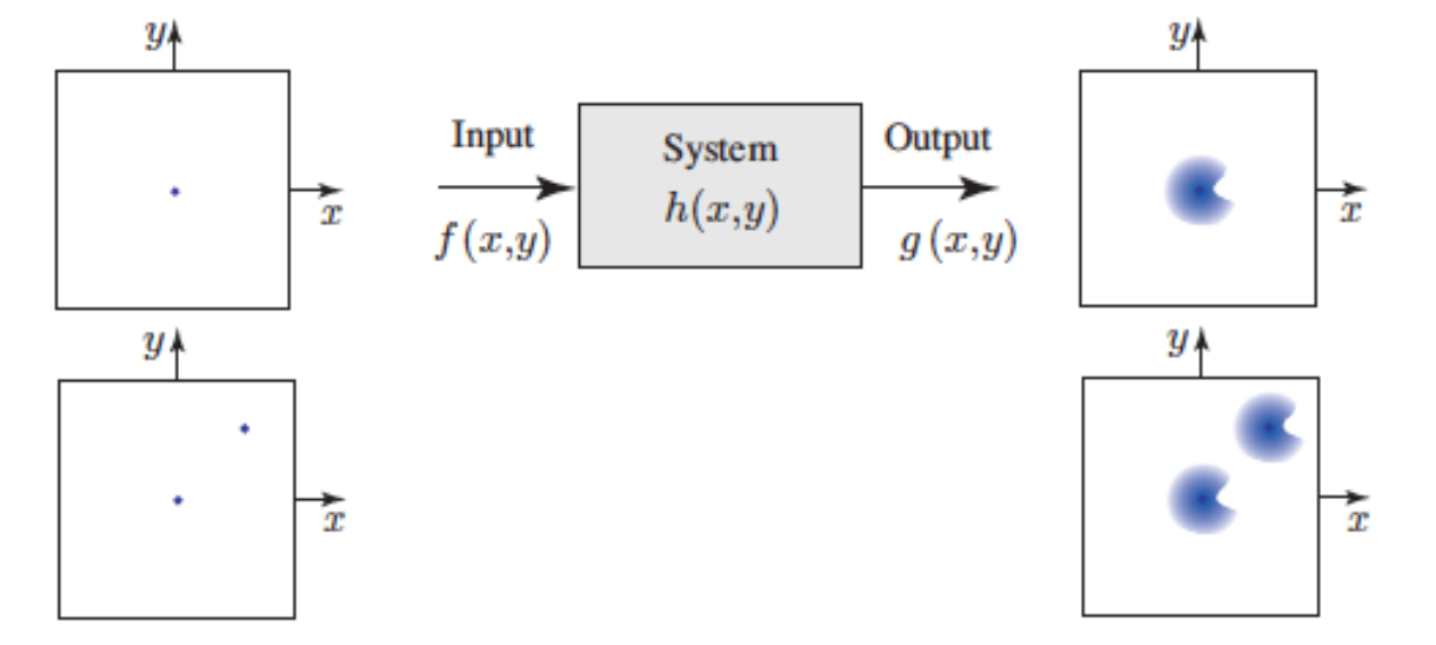

**ILL. 2.1*** 2-dimensional shift invariant system.*

2-dimensional convolution operation for analog signal : 

$g\left(x,y\right)=\int_{-\infty }^{\infty } \int_{-\infty }^{\infty } h\left(x-x^{\prime } ,y-y^{\prime } \right)f\left(x^{\prime } ,y^{\prime } \right){\textrm{dx}}^{\prime } {\textrm{dy}}^{\prime } \equiv h\left(x,y\right)\otimes f\left(x,y\right)$.

2-dimensional convolution operation for discrete signal : 

$g\left\lbrack x,y\right\rbrack =\sum_{n^{\prime } ,m^{\prime } } h\left\lbrack n-n^{\prime } ,m-m^{\prime } \right\rbrack f\left\lbrack n^{\prime } ,m^{\prime } \right\rbrack$.

Depending on the elements of the convolution kernel, the LSI system examples we roughly put into additive and subtractive filter categories. The kernels, $h\left\lbrack n,m\right\rbrack$, of all the examples are finite arrays. These type of filters are called finite impulse response (FIR) filters. Of course, the kernels can be infinte arrays, which are called infinite impulse response (IIR) filters. We do not discuss the IIR here. Interested readers are welcomed to check the excellent textbook: *Discrete-Time Signal Processing (Prentice Hall Signal Processing), 3rd Edition* by A. Openheim and R. Schafer.

### **2.1 Additive filters**

Below are some of the most common additive filters.

**Nearest-neighbor uniform averaging: **The gray value at each pixel of the output is simply the average of the 4 nearest neighboring pixels surrounding and including the pixel.

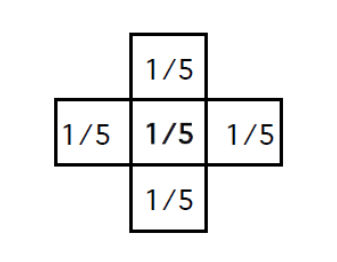

**ILL. 2.2** *Nearest-neighbor uniform averaging*

**3x3 box filter: **In this case, the spread is over a large window of 3x3 pixels. The gray value at each pixel of the output is simply the average of the 8  surrounding pixels and the center pixel itself.

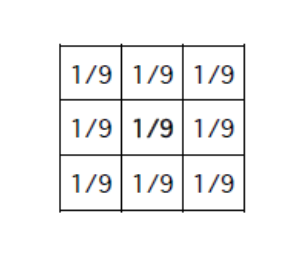

**ILL. 2.3** *3x3 box filter*

**3x1 uniform averaging: **Here the window extends only in the horizontal direction, so that the averaging is over the pixel and its right and left neighbor. There is no spread in the vertical direction.

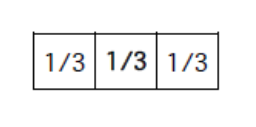

**ILL. 2.4** *3x1 uniform averaging*

**Non-uniform averaging: **The weights of the receptive fields need not to be uniform. In the shown example the central point is given a 20% weight, the four nearest neighbors are given a weight of 15% each, and the remaining four neighbors are given a weight of 5% each.

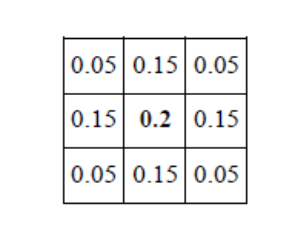

**ILL. 2.5** *Non-uniform averaging*

***Example 2.1 ***

Nearest-neighbor uniform averaging filter

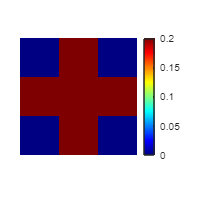

k=1;
Kernel=zeros(2*k+1);
Kernel(2,:)=1/5;
Kernel(:,2)=1/5;

figure;
imagesc(Kernel);
axis image;axis equal;axis off;
colormap('jet');colorbar;
set(gcf,'Position',[100 100 200 200]);

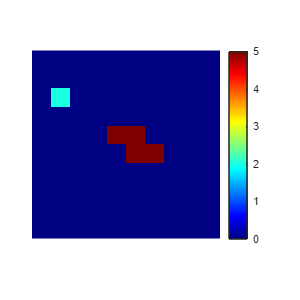

% input
m=10;
n=10;
InputImg=zeros(m,n);
InputImg(3,2)=2;
InputImg(5,5:6)=5;
InputImg(6,6:7)=5;

figure;
imagesc(InputImg);
axis image;axis equal;axis off;
colormap('jet');colorbar;
set(gcf,'Position',[100 100 300 300]);

% calculate convolution output using convolution by definition.
OutputImg=zeros(m+2*k+1,n+2*k+1);
tic;
for ii=1:m
    for jj=1:n
        OutputImg(ii+k+(-k:k),jj+k+(-k:k))=InputImg(ii,jj).*Kernel...
            +OutputImg(ii+k+(-k:k),jj+k+(-k:k));
    end
end
toc,

Elapsed time is 0.003989 seconds.


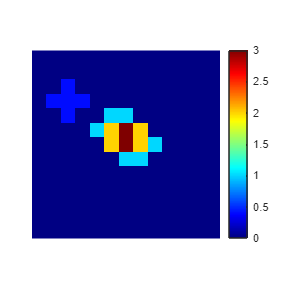


figure;
imagesc(OutputImg);
axis image;axis equal;axis off;
colormap('jet');colorbar;
set(gcf,'Position',[100 100 300 300]);

%% There is a time difference. Why?
tic;
OutputImg2=conv2(Kernel,InputImg);
toc,

Elapsed time is 0.072952 seconds.


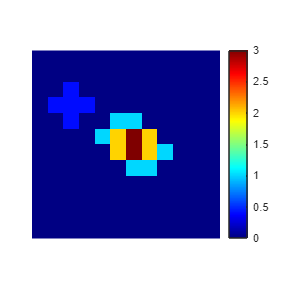

figure;
imagesc(OutputImg2);
axis image;axis equal;axis off;
colormap('jet');colorbar;
set(gcf,'Position',[100 100 300 300]);

***Example 2.2 ***

Receptive function of nearest-neighbor uniform averaging filter.

The receptive function is an inverted version of the point spread function (PSF).


$$\eta \left(x,y\right)=h\left(-x,-y\right)$$


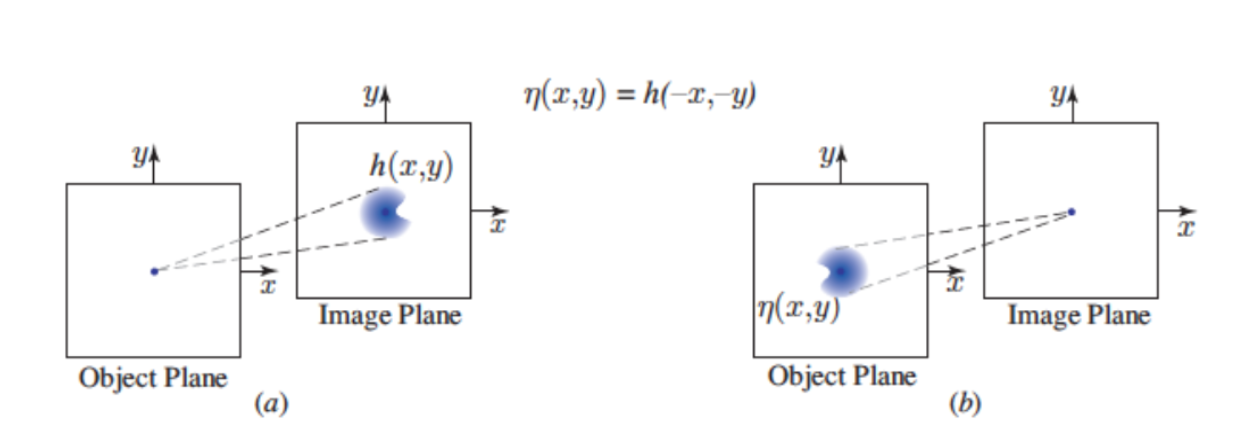

**ILL. 2.6*** a) Point spread function. b) Receptive function.*

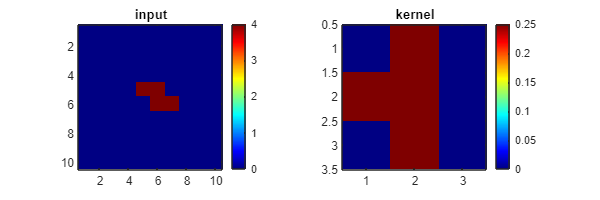

%%input
m=10;
n=10;
InputImg2=zeros(m,n);
InputImg2(5,5:6)=4;
InputImg2(6,6:7)=4;

% kernel function
k=1;
Kernel2=zeros(2*k+1);
Kernel2(2,:)=1/4;
Kernel2(:,2)=1/4;
Kernel2(2,3)=0;

figure;
subplot(121)
imagesc(InputImg2);
title('input')
axis image;axis equal;
colormap('jet');colorbar;
subplot(122)
imagesc(Kernel2);
title('kernel')
axis image;axis equal;
colormap('jet');colorbar;
set(gcf,'Position',[100 100 600 200]);

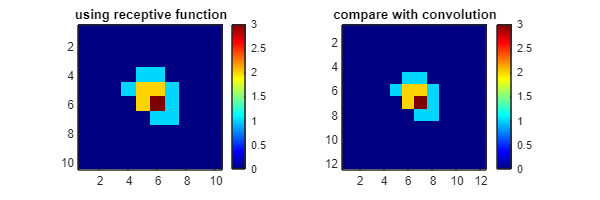

% calculate convolution output using receptive function.
Recep = rot90(Kernel2,2);% receptive function
OutputImg3=zeros(m,n);
InputImg2_pad = padarray(InputImg2, [k+1,k+1],0,'both');% pad 0 to original image
for ii=1:m
    for jj=1:n
        OutputImg3(ii,jj) = sum(InputImg2_pad(ii+k+1+(-k:k),jj+k+1+(-k:k)).*Recep,'all');
    end
end

OutputImg4=conv2(Kernel2,InputImg2); % compare with convlution results

figure;
subplot(121)
imagesc(OutputImg3);
title('using receptive function')
axis image;axis equal;
colormap('jet');colorbar;

subplot(122)
imagesc(OutputImg4);
axis image;axis equal;
title('compare with convolution')
colormap('jet');colorbar;
set(gcf,'Position',[100 100 600 200]);

### **2.2 Subtractive filters**

Here are some of the popular subtractive filters. As shown in the examples below, the difference operation in discrete systems is the analog of the derivative in continuous system.

**The vertical difference:**

Partial derivative:  


$$\frac{\partial f}{\partial x}=\lim_{\Delta x\longrightarrow 0} \frac{f\left(x+\Delta x,y\right)-f\left(x,y\right)}{\Delta x}$$


The difference operation: 


$$g\left\lbrack n,m\right\rbrack =f\left\lbrack n+1,m\right\rbrack -f\left\lbrack n,m\right\rbrack$$


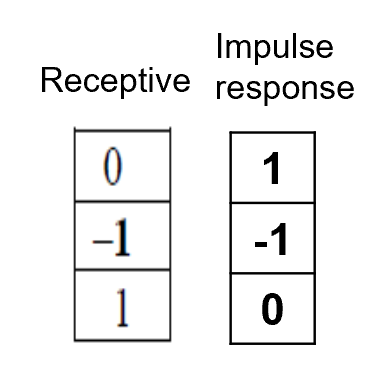

**ILL. 2.7*** The vertical difference operation*

**The horizontal difference: **

The difference operation: 


$$g\left\lbrack n,m\right\rbrack =f\left\lbrack n,m+1\right\rbrack -f\left\lbrack n,m\right\rbrack$$


It's equivalent to a partial derivative : 


$$g=\frac{\partial f}{\partial x}$$


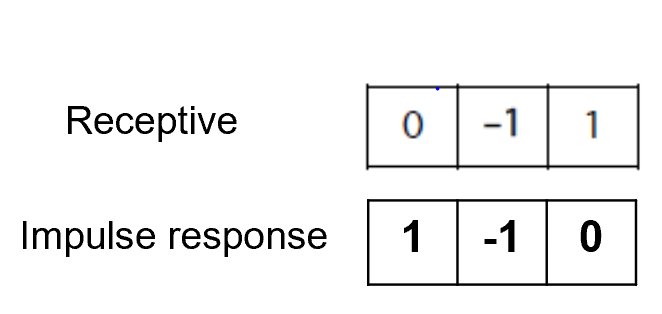

**ILL. 2.8*** The horizontal difference operation*

**Second order horizontal:**

The difference operation: 


$$g\left\lbrack n,m\right\rbrack =\left(f\left\lbrack n,m+1\right\rbrack -f\left\lbrack n,m\right\rbrack \right)-\left(f\left\lbrack n,m\right\rbrack -f\left\lbrack n,m-1\right\rbrack \right)=f\left\lbrack n,m+1\right\rbrack -2f\left\lbrack n,m\right\rbrack +f\left\lbrack n,m-1\right\rbrack$$


It's equivalent to a partial derivative : 


$$g=\frac{\partial^2 f}{\partial y^2 }$$


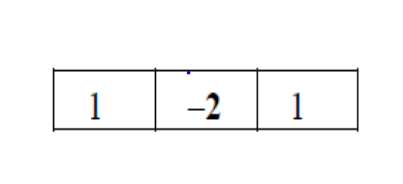

**ILL. 2.9** *Second order horizontal difference operation*

**Second order two dimensional :**

The difference operation: 


$$g\left\lbrack n,m\right\rbrack =\left(f\left\lbrack n+1,m\right\rbrack -2f\left\lbrack n,m\right\rbrack +f\left\lbrack n-1,m\right\rbrack \right)+\left(f\left\lbrack n,m+1\right\rbrack -2f\left\lbrack n,m\right\rbrack +f\left\lbrack n,m+1\right\rbrack \right)$$


It's equivalent to the partial derivative : 


$$g=\frac{\partial^2 f}{\partial x^2 }+\frac{\partial^2 f}{\partial y^2 }$$


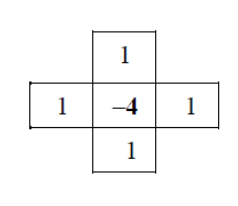

**ILL. 2.10*** Second order two dimensional difference operation*

***Example 2.3 ***

Horizontal difference operation.

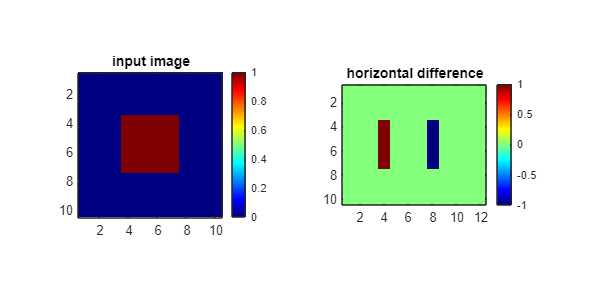

Kernel_d=[1,-1,0]; % The horizontal difference

%Input image
m=10;
n=10;
InputImg=zeros(m,n);
InputImg(4:7,4:7)=1;
OutputImg=conv2(Kernel_d,InputImg);

figure;
subplot(121)
imagesc(InputImg);
title('input image');
axis image;axis equal;
colormap('jet');colorbar;
subplot(122)
imagesc(OutputImg);
title('horizontal difference');
axis image;axis equal;
colormap('jet');colorbar;
set(gcf,'Position',[100 100 600 300]);

### 2.3 Match filtering

As shown in ILL. 2.11, match filtering is used to look for a sub-image $\eta$ in a given image $f$. In this process, the maximum pixel value of the convolution of $f$ and $\eta$ shows us the location of sub-image $\eta$.

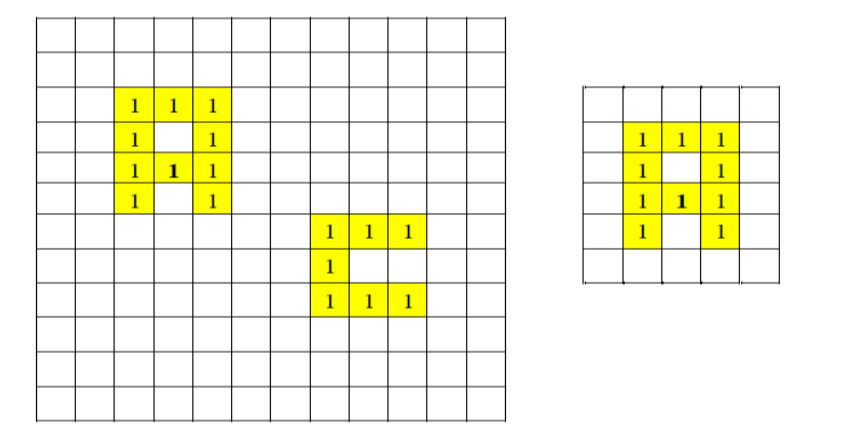

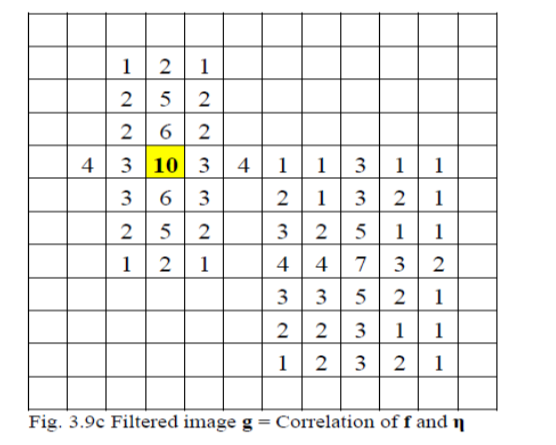

**ILL. 2.11*** Match filtering*

***Example 1.5.Match filtering***

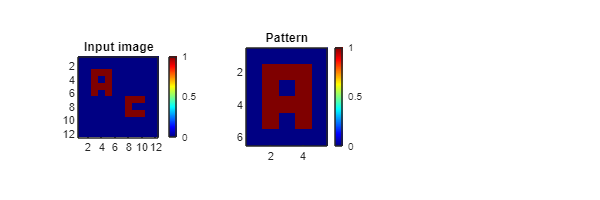

%input
m=12;
n=12;
InputImg=zeros(m,n);
InputImg(3:6,3:5)=1;
InputImg(7:9,8:10)=1;
InputImg(4,4)=0;InputImg(6,4)=0;
InputImg(8,9)=0;InputImg(8,10)=0;
% Pattern to be recognized
Pattern = zeros(6,5);
Pattern(2:5,2:4)=1;
Pattern(3,3)=0;
Pattern(5,3)=0;
figure;
subplot(131);
imagesc(InputImg);
title('Input image');
axis image;
colormap('jet');colorbar;
subplot(132);
imagesc(Pattern);
title('Pattern');
axis image;
colormap('jet');colorbar;
set(gcf,'Position',[100 100 600 200]);

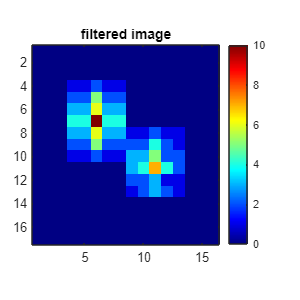

OutputImg=conv2(rot90(Pattern,2),InputImg);

figure;
imagesc(OutputImg);
title('filtered image');
axis image;
colormap('jet');colorbar;
set(gcf,'Position',[100 100 300 300]);